## **Modelando**

## Boas Práticas

clear all;
close all;
clc;

## Lendo os dados reias a partir de um arquivo .txt

%%% Ler o arquivo de dados

leitor_dados;

%%% Especificando o tempo - eixo x

Ts    = 1e-3;                       % taxa de amostargem do sistema de aquisição - 1ms
tempo = linspace(0,4685*Ts,4685);   % vetor tempo para análise dos sinais

## Visualizando os dados

figure(1)

subplot(3,1,1)

plot(tempo, Entrada, 'LineWidth', 2)
title('Dados de um motor CC - entrada')
xlabel('tempo em segundos')
ylabel('tensão em volts')
grid

subplot(3,1,2)

plot(tempo, Velocidade, 'LineWidth', 2)
title('Dados de um motor CC - velocidade')
xlabel('tempo em segundos')
ylabel('tensão em volts')
grid

subplot(3,1,3)

plot(tempo, Posicao, 'LineWidth', 2)
title('Dados de um motor CC - posicao')
xlabel('tempo em segundos')
ylabel('tensão em volts')
grid

## Estimando um modelo em Laplace para os dados

O sinal de entrada $U(s)$ foi aplicado a um sistema cuja função de transferência gerou o sinal $\Omega(s)$. Logo a relação entre entrada e saída é dada pela função de transferência:

$\frac{\Omega(s)}{U(s)} =  \frac{K_m}{s+p_m}$ . Neste caso supomos ser de primera ordem pelo aspecto geral do sinal **Rotação**.

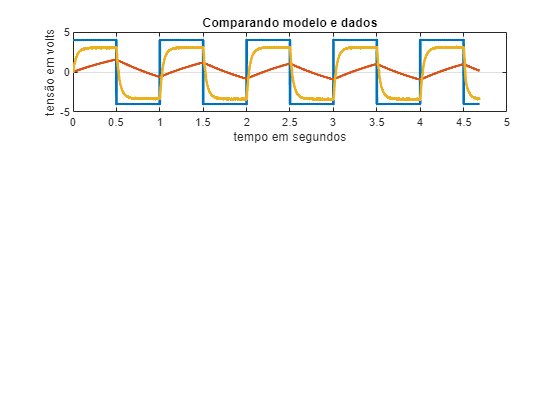

%%% Valore iniciais de Km e pm
Km = 1;
pm = 1;

%%% Criando a função de transferência do modelo

Gp = tf(Km, [1 pm]);

%%% Simular o modelo com a mesma entrada

ym = lsim(Gp, Entrada, tempo);

figure(2)

subplot(3,1,1)

plot(tempo, Entrada, tempo, ym, tempo, Velocidade, 'LineWidth', 2)
title('Comparando modelo e dados')
xlabel('tempo em segundos')
ylabel('tensão em volts')
grid

## Sintonizando os valores do modelo a partir dos dados

## Comparando o modelo com os dados